# Linear Filtering

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2020-12-10

### Low vs High Frequency


$$x\left(t\right)=\sum_{n=0}^{\infty } \frac{2}{n\pi }\left(1-\textrm{cosn}\pi \right)\sin \left(\frac{2\pi \textrm{nt}}{T_p }\right)$$


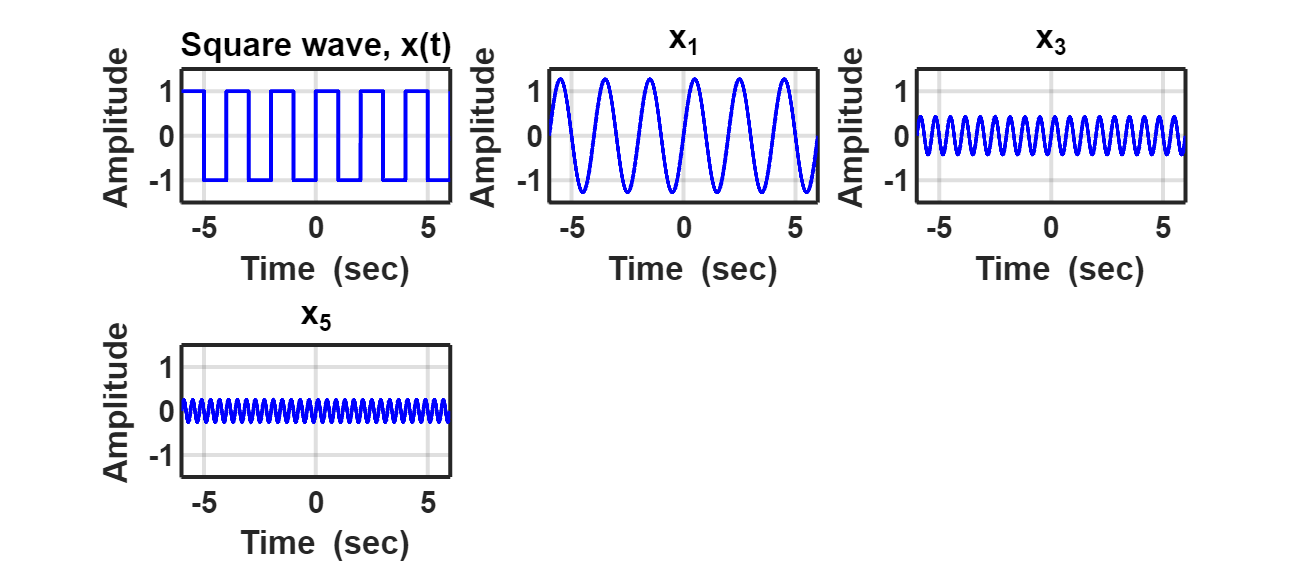

clear; clc ; close all;

% this signal is assumed to be analog. 
ncyle = 3;
Fsa = 1000; % # of samples per a second (assumed to be infinite)
Tp = 2;
t = -ncyle*Tp:1/Fsa:ncyle*Tp;
x = @(t) square(t*(2*pi)/Tp); % original signal

nCoeff = 5;

sig_y_analytic = zeros(nCoeff, numel(t));

% analytic integration

for ii=1:nCoeff
    sig_y_analytic(ii,:) = 2/(ii*pi)*(1-cos(ii*pi))*sin(2*pi*ii*t/Tp);
end

fig1 = figure(1);
set(fig1,'Position', [100 100 1800 800]);

subplot(231); plot(t,x(t),'-b', 'linewidth', 2);
axis tight;grid on;
title('Square wave, x(t)')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(232); 
plot(t,sig_y_analytic(1,:),'b', 'linewidth', 2);
axis tight;grid on; hold off;
title('x_1')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(233); 
plot(t,sig_y_analytic(3,:),'b', 'linewidth', 2);
axis tight;grid on; hold off;
title('x_3')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold'); 

subplot(234); 
plot(t,sig_y_analytic(nCoeff,:),'b', 'linewidth', 2);
axis tight;grid on; hold off;
title('x_5')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

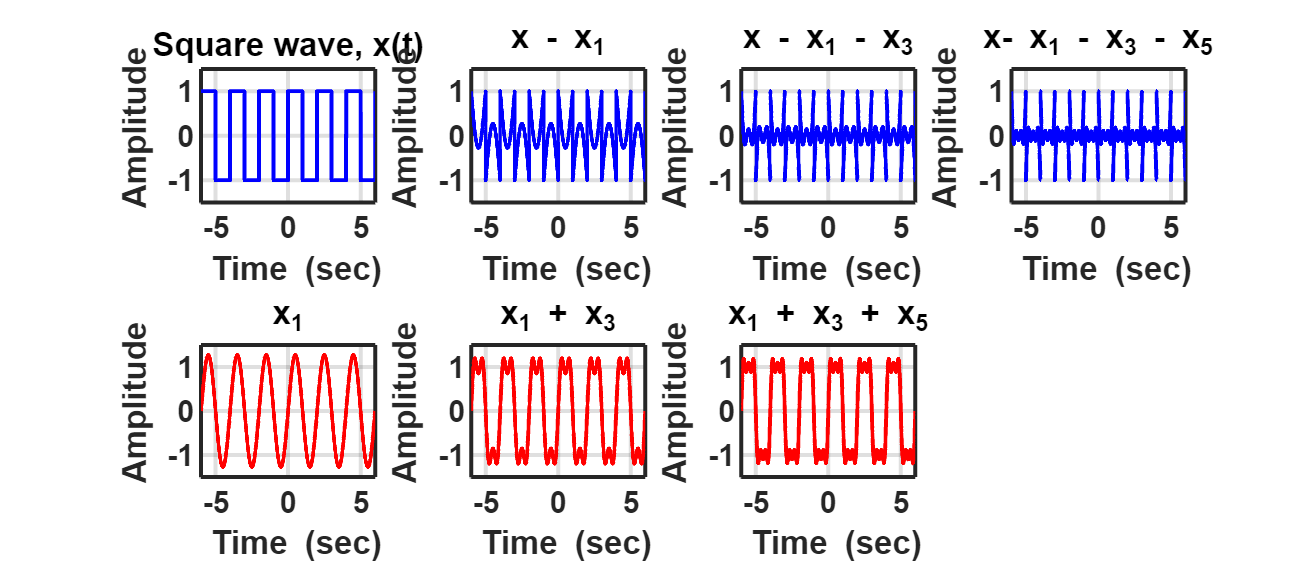


fig2 = figure(2);
set(fig2,'Position', [100 100 1800 800]);

subplot(241); plot(t,x(t),'-b', 'linewidth', 2);
axis tight;grid on;
title('Square wave, x(t)')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(242); 
plot(t,x(t)-sig_y_analytic(1,:),'b', 'linewidth', 2);
axis tight;grid on; hold off;
title('x - x_1')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(243); 
plot(t,x(t)- sig_y_analytic(1,:) - sig_y_analytic(3,:),'b', 'linewidth', 2);
axis tight;grid on; hold off;
title('x - x_1 - x_3')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold'); 

subplot(244); 
plot(t,x(t)- sig_y_analytic(1,:) - sig_y_analytic(3,:) - sig_y_analytic(5,:),'b', 'linewidth', 2);
axis tight;grid on; hold off;
title('x- x_1 - x_3 - x_5')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(245); 
plot(t,sig_y_analytic(1,:),'r', 'linewidth', 2);
axis tight;grid on; hold off;
title('x_1')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold'); 

subplot(246); plot(t,sig_y_analytic(1,:) + sig_y_analytic(3,:),'-r', 'linewidth', 2);
axis tight;grid on;
title('x_1 + x_3')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(247); 
plot(t,sig_y_analytic(1,:) + sig_y_analytic(3,:) + sig_y_analytic(5,:),'r', 'linewidth', 2);
axis tight;grid on; hold off;
title('x_1 + x_3 + x_5')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

### **Frequency Image (Simple Pattern)**

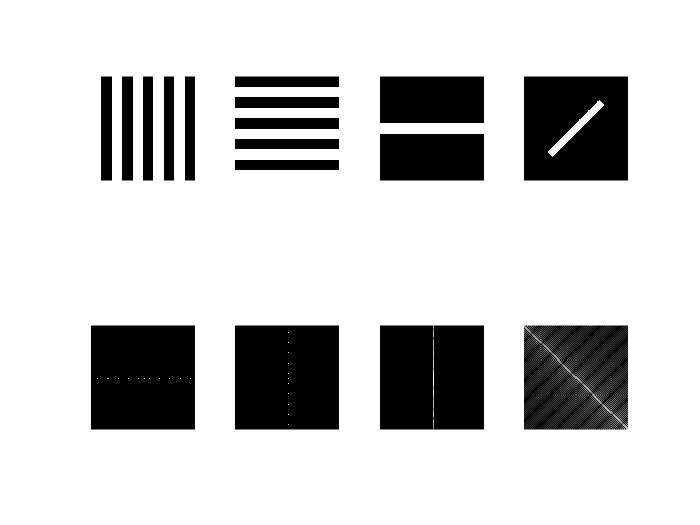

% horzontal pattern
img_hp = repmat(repelem([1 0], 40), 400, 5);
imgf = fftshift(fft2(img_hp));
img_hpf = rescale(log(abs(imgf)+1));  

% vertical pattern
img_vp = imrotate(img_hp, 90);
imgf = fftshift(fft2(img_vp));
img_vpf = rescale(log(abs(imgf)+1));  

% horzontal bar
img_hb = zeros(400, 400);
img_hb(180:220, :) = 1;
imgf = fftshift(fft2(img_hb));
img_hbf = rescale(log(abs(imgf)+1));  

% diagonal bar
img_db = imrotate(img_hb, 45);
imgf = fftshift(fft2(img_db));
img_dbf = rescale(log(abs(imgf)+1));  

figure(1); 
subplot(241); imshow(img_hp);
subplot(242); imshow(img_vp);
subplot(243); imshow(img_hb);
subplot(244); imshow(img_db);

subplot(245); imshow(img_hpf(150:250,150:250))
subplot(246); imshow(img_vpf(150:250,150:250))
subplot(247); imshow(img_hbf(150:250,150:250))
subplot(248); imshow(img_dbf(150:250,150:250))

### **Frequency Image**

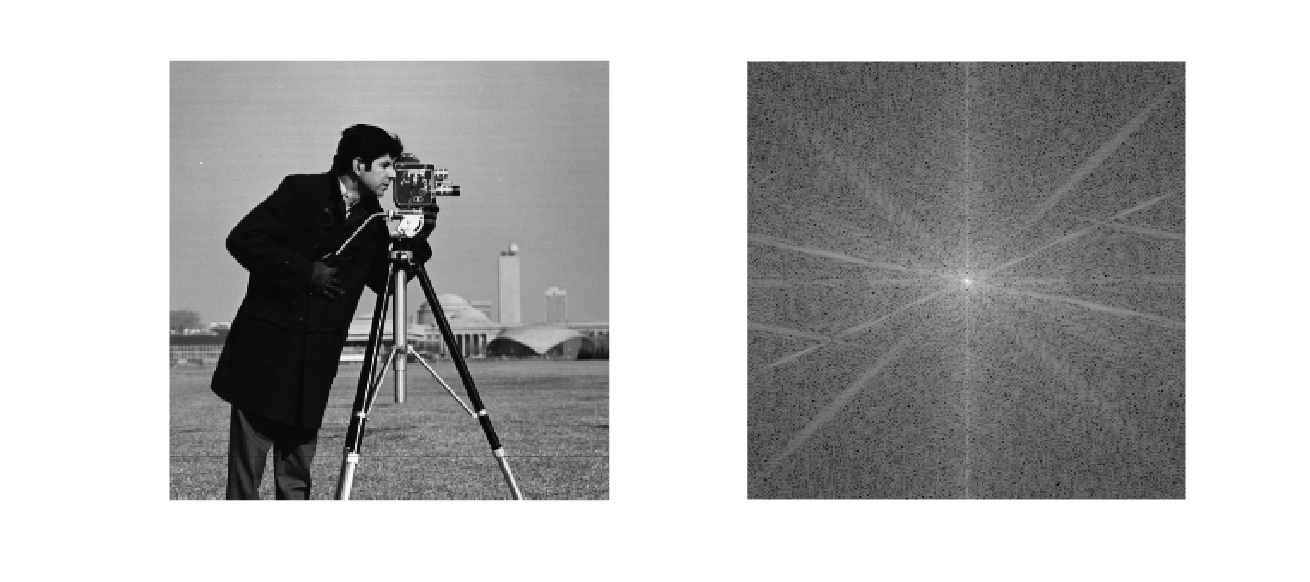

clear; close all; clc
img = imread('cameraman.tif');
imgf = fftshift(fft2(img));
imgf = rescale(log(abs(imgf)+1));  

fig1 = figure(1);
set(fig1,'Position', [100 100 1800 800]);

subplot(121); imshow(img);
subplot(122); imshow(imgf);

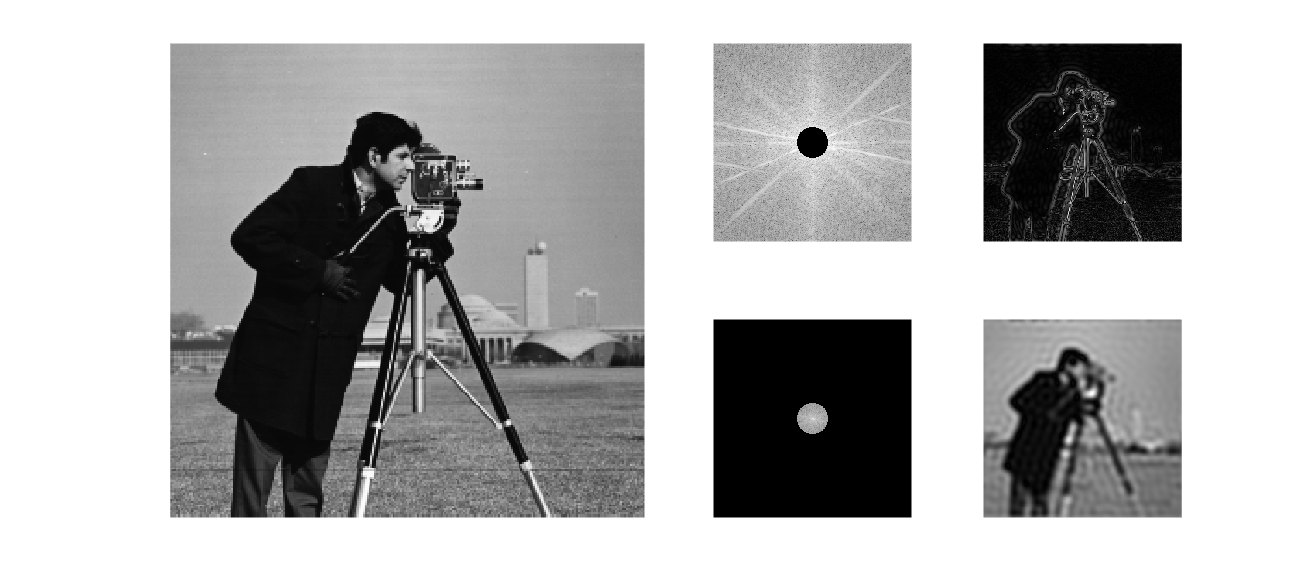



mask = ones(size(img));
[ii,jj] = ind2sub(size(mask), find(mask(:)));

c_sz = 20;

ind_circle = ((ii-128.5).^2 + (jj-128.5).^2) < c_sz^2;
ind_out = ((ii-128.5).^2 + (jj-128.5).^2) >= c_sz^2;

fig2 = figure(2);
set(fig2,'Position', [100 100 1800 800]);

subplot(2,4,[1 2 5 6]); imshow(img);

img = imread('cameraman.tif');
imgf_low = fftshift(fft2(img));
imgf_low(ind_circle) = 0;
subplot(243); imshow(rescale(log(abs(imgf_low)+1)));

imgf_low = ifftshift(imgf_low);
img_low = ifft2(imgf_low);
subplot(244); imshow(rescale(abs(img_low)));

img = imread('cameraman.tif');
imgf_high = fftshift(fft2(img));
imgf_high(ind_out) = 0;
subplot(247); imshow(rescale(log(abs(imgf_high)+1)));

imgf_high = ifftshift(imgf_high);
imgf_high = ifft2(imgf_high);
subplot(248); imshow(rescale(abs(imgf_high)));

**Convolution Vs Cross-Correlation**

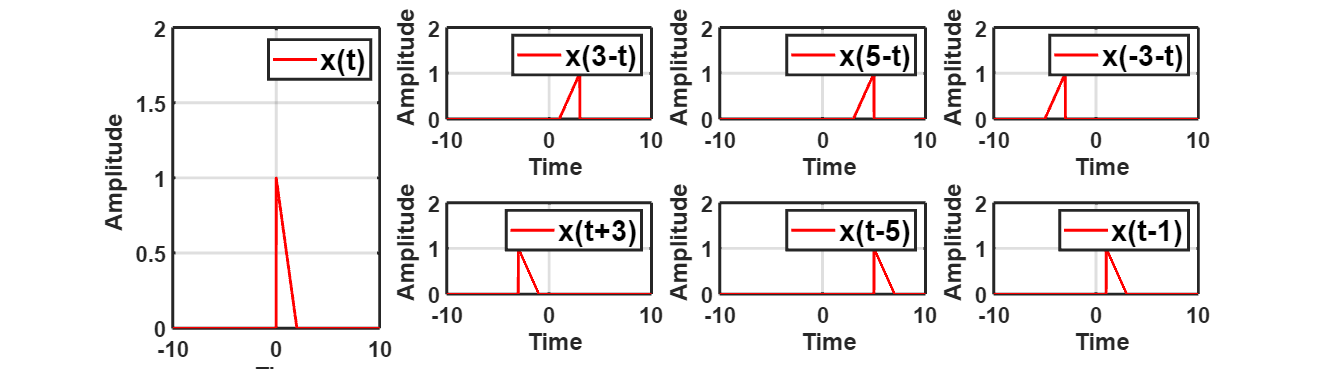

clear; clc ; close all;

syms t   

sig1 = @(t) (-0.5*t + 1).*(t<=2 & t>=0);

t = -10:0.01:10;

fig1 = figure(1);
set(fig1,'Position', [100 100 1800 500]);

subplot(2,4, [1 5]); plot(t,sig1(t),'-r', 'linewidth', 2);hold on;
lgd = legend('x(t)'); lgd.FontSize = 20; axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 2])
xlabel('\bf Time');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(242); plot(t,sig1(3-t),'-r', 'linewidth', 2);hold on;
lgd = legend('x(3-t)'); lgd.FontSize = 20; axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 2])
xlabel('\bf Time');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(243); plot(t,sig1(5-t),'-r', 'linewidth', 2);hold on;
lgd = legend('x(5-t)'); lgd.FontSize = 20; axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 2])
xlabel('\bf Time');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(244); plot(t,sig1(-3-t),'-r', 'linewidth', 2);hold on;
lgd = legend('x(-3-t)'); lgd.FontSize = 20; axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 2])
xlabel('\bf Time');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(246); plot(t,sig1(t+3),'-r', 'linewidth', 2);hold on;
lgd = legend('x(t+3)'); lgd.FontSize = 20; axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 2])
xlabel('\bf Time');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(247); plot(t,sig1(t-5),'-r', 'linewidth', 2);hold on;
lgd = legend('x(t-5)'); lgd.FontSize = 20; axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 2])
xlabel('\bf Time');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(248); plot(t,sig1(t-1),'-r', 'linewidth', 2);hold on;
lgd = legend('x(t-1)'); lgd.FontSize = 20; axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 2])
xlabel('\bf Time');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

### Identical Filter

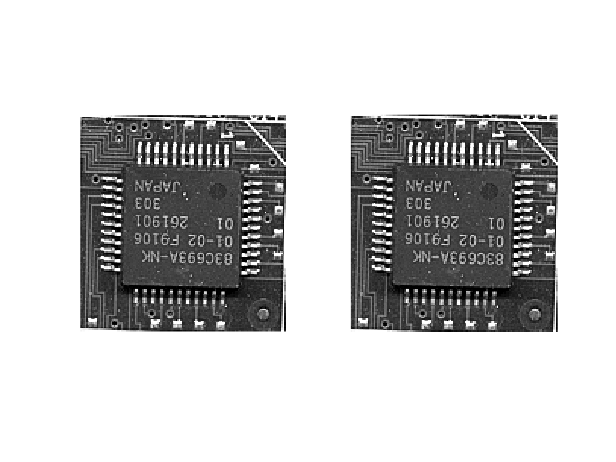

img = imread('board.tif');
bbox = [7.5100  152.5100  135.9800  142.9800];
patch = rgb2gray(imcrop(img, bbox));
patch = im2double(patch);
k1 = zeros(3,3);
k1(2,2) = 1;

figure(11)
subplot(121); imshow(patch);
subplot(122); imshow(conv2(patch, k1, 'same'))

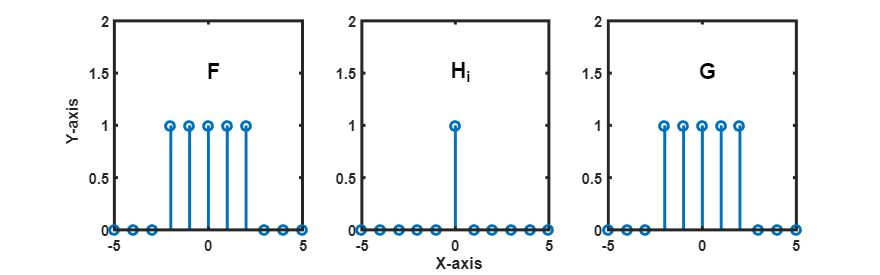


x = -5:1:5;
% G = H*F;
F = zeros(size(x)); F(4:8)=1;
H = zeros(size(x)); H(6)=1;
G = conv(F, H, 'same');

fig2 = figure(12);
ax1= subplot(131);stem(x,F,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2]);
text(0, 1.5,'\bf F','fontSize', 15, 'HorizontalAlignment', 'center')
ax2= subplot(132);stem(x,H,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2])
text(0, 1.5,'\bf H_i','fontSize', 15, 'HorizontalAlignment', 'center')
ax3 = subplot(133);stem(x,G,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2])
text(0, 1.5,'\bf G','fontSize', 15, 'HorizontalAlignment', 'center')
xlabel(ax2, '\bf X-axis');
ylabel(ax1, '\bf Y-axis'); 
set(fig2,'Position', [100 100 800 250]);

### Shifting Filter

clear
img = imread('board.tif');
bbox = [7.5100  152.5100  135.9800  142.9800];
patch = rgb2gray(imcrop(img, bbox));

'imcrop' requires Image Processing Toolbox.

patch = im2double(patch);

k1 = zeros(3,3);
k1(2,3) = 1;

figure(11)
subplot(121); imshow(patch);
subplot(122); imshow(conv2(patch, k1, 'same'))

x = -5:1:5;
% G = H*F;
F = zeros(size(x)); F(4:8)=1;
H = zeros(size(x)); H(8)=1;
G = conv(F, H, 'same');

fig2 = figure(12);
ax1= subplot(131);stem(x,F,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2]);
text(0, 1.5,'\bf F','fontSize', 15, 'HorizontalAlignment', 'center')
ax2= subplot(132);stem(x,H,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2])
text(0, 1.5,'\bf H_s','fontSize', 15, 'HorizontalAlignment', 'center')
ax3 = subplot(133);stem(x,G,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2])
text(0, 1.5,'\bf G','fontSize', 15, 'HorizontalAlignment', 'center')
xlabel(ax2, '\bf X-axis');
ylabel(ax1, '\bf Y-axis'); 
set(fig2,'Position', [100 100 800 250]);

### Blurring Filter

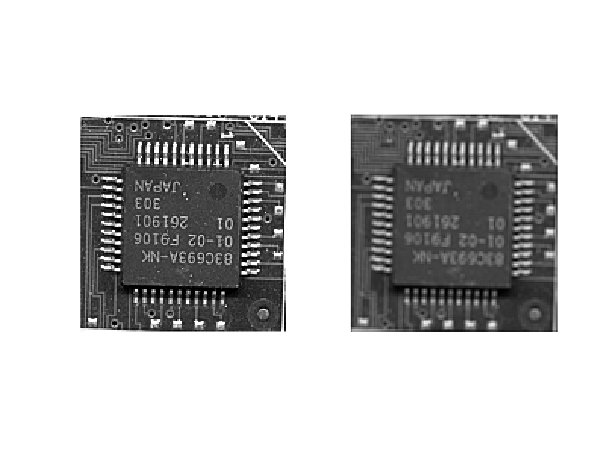

clear
img = imread('board.tif');
bbox = [7.5100  152.5100  135.9800  142.9800];
patch = rgb2gray(imcrop(img, bbox));
patch = im2double(patch);

k1 = ones(3,3)/9;

figure(11)
subplot(121); imshow(patch);
subplot(122); imshow(conv2(patch, k1, 'same'))

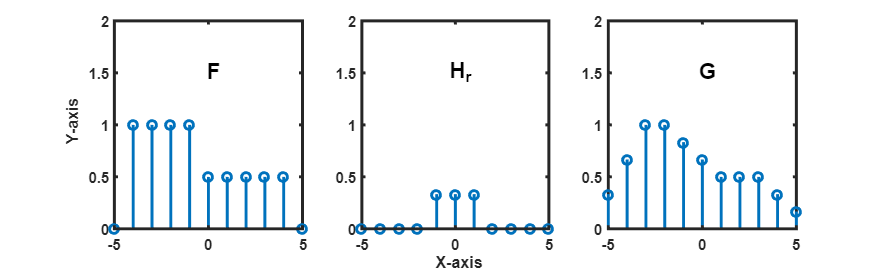


x = -5:1:5;
% G = H*F;
F = zeros(size(x)); F(2:5)=1; F(6:end-1)=0.5;
H = zeros(size(x)); H(5:7)=1/3;
G = conv(F, H, 'same');

fig2 = figure(12);
ax1= subplot(131);stem(x,F,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2]);
text(0, 1.5,'\bf F','fontSize', 15, 'HorizontalAlignment', 'center')
ax2= subplot(132);stem(x,H,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2])
text(0, 1.5,'\bf H_r','fontSize', 15, 'HorizontalAlignment', 'center')
ax3 = subplot(133);stem(x,G,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2])
text(0, 1.5,'\bf G','fontSize', 15, 'HorizontalAlignment', 'center')
xlabel(ax2, '\bf X-axis');
ylabel(ax1, '\bf Y-axis'); 

set(fig2,'Position', [100 100 800 250]);

### Shapening Filter

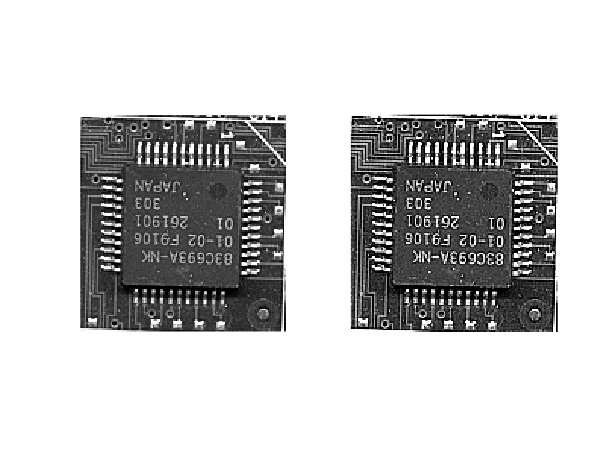

k1 = zeros(3,3);
k1(2,2)= 2;
k1 = k1 - ones(3,3)/9;

figure(11)
subplot(121); imshow(patch);
subplot(122); imshow(conv2(patch, k1, 'same'))

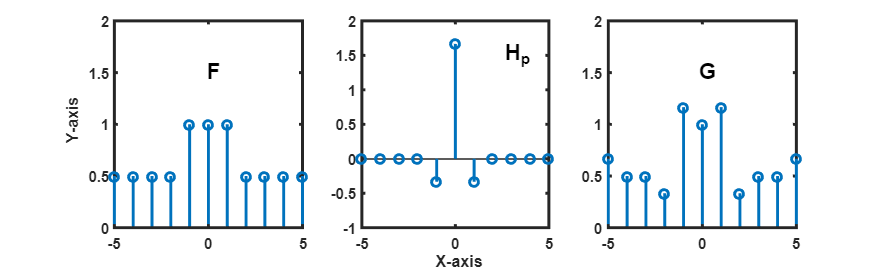


x = -5:1:5;
% G = H*F;
F = zeros(size(x)); F(:) = 1; F(1:4)=0.5; F(end-3:end)=0.5;
H = zeros(size(x)); H(5)=-1/3; H(7)=-1/3; H(6)=5/3;
G = conv(F, H, 'same');

fig2 = figure(12);
ax1= subplot(131);stem(x,F,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2]);
text(0, 1.5,'\bf F','fontSize', 15, 'HorizontalAlignment', 'center')
ax2= subplot(132);stem(x,H,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([-1 2])
text(3, 1.5,'\bf H_p','fontSize', 15, 'HorizontalAlignment', 'center')
ax3 = subplot(133);stem(x,G,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2])
text(0, 1.5,'\bf G','fontSize', 15, 'HorizontalAlignment', 'center')
xlabel(ax2, '\bf X-axis');
ylabel(ax1, '\bf Y-axis'); 

set(fig2,'Position', [100 100 800 250]);

### Understanding of a Sharpening Filter (1D Example)

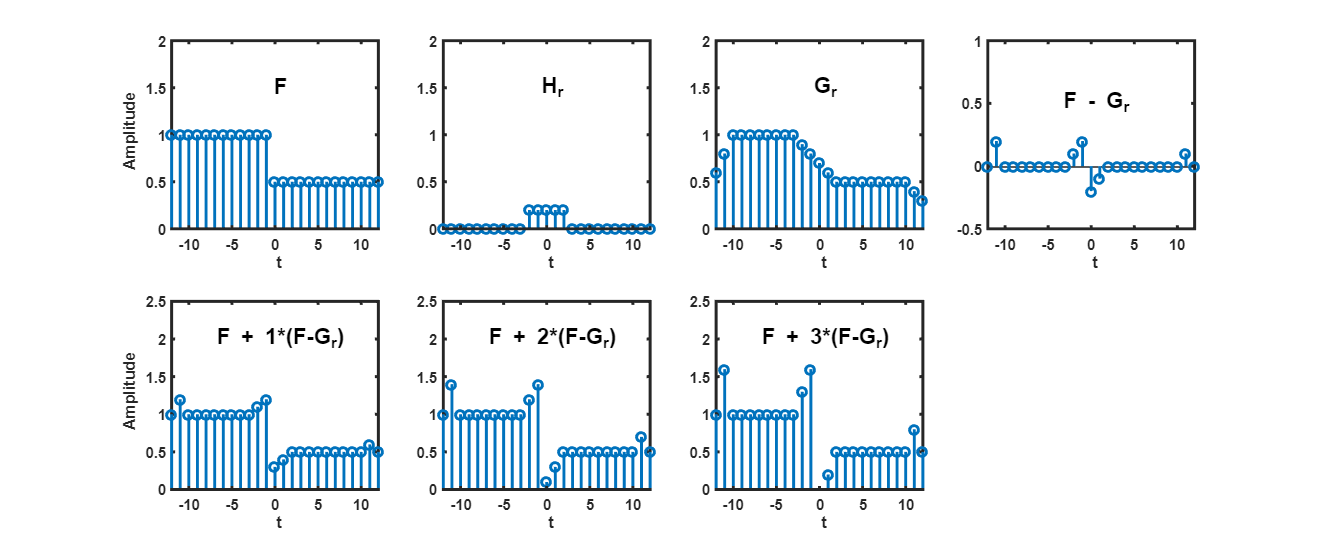

clear; close all; clc;

x = -12:1:12;

% G = H*F;
F = zeros(size(x)); F(1:12) = 1; F(13:end)=0.5;
H = zeros(size(x)); H(11:15) = 1/5;
G = conv(F, H, 'same');

fig1 = figure(1);
set(fig1,'Position', [100 100 1200 500]);

ax1= subplot(241);stem(x,F,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2]);
text(0, 1.5,'\bf F','fontSize', 15, 'HorizontalAlignment', 'center')
xlabel('\bf t');
ylabel(ax1, '\bf Amplitude'); 

subplot(242);stem(x,H,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2])
text(0, 1.5,'\bf H_r','fontSize', 15, 'HorizontalAlignment', 'center')
xlabel('\bf t');

subplot(243);stem(x,G,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2])
text(0, 1.5,'\bf G_r','fontSize', 15, 'HorizontalAlignment', 'center')
xlabel('\bf t');

F_G = F-G; F_G(1) = 0; F_G(end) =0;
subplot(244);stem(x,F_G,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([-0.5 1]);
text(0, 0.5,'\bf F - G_r','fontSize', 15, 'HorizontalAlignment', 'center')
xlabel('\bf t');


alpha = 1;
ax2= subplot(245);stem(x,F+alpha*F_G,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2.5]);
text(0, 2,'\bf F + 1*(F-G_r)','fontSize', 15, 'HorizontalAlignment', 'center')
xlabel('\bf t');
ylabel(ax2, '\bf Amplitude'); 

alpha = 2;
subplot(246);stem(x,F+alpha*F_G,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2.5]);
text(0, 2,'\bf F + 2*(F-G_r)','fontSize', 15, 'HorizontalAlignment', 'center')
xlabel('\bf t');

alpha = 3;
subplot(247);stem(x,F+alpha*F_G,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2.5]);
text(0, 2,'\bf F + 3*(F-G_r)','fontSize', 15, 'HorizontalAlignment', 'center')
xlabel('\bf t');

### Understanding of a Sharpening Filter (2D Example)

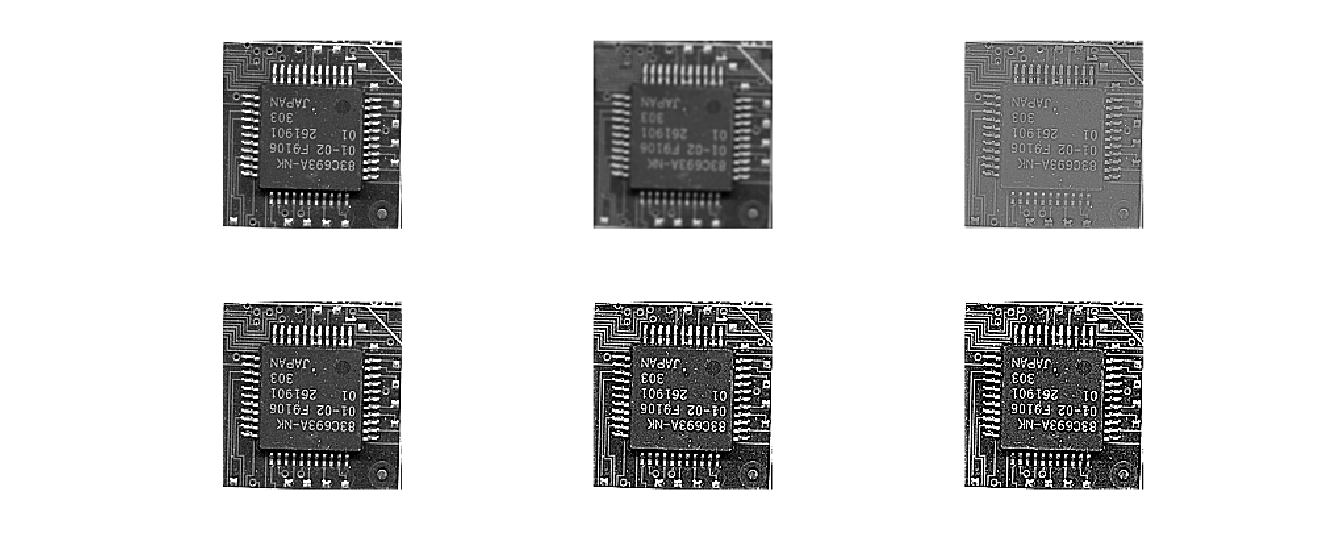

clear; close all; clc;

img = imread('board.tif');
bbox = [7.5100  152.5100  135.9800  142.9800];
patch = rgb2gray(imcrop(img, bbox));
patch = im2double(patch);

k1 = zeros(3,3);
k1(2,2)= 2;
k1 = k1 - ones(3,3)/9;

fig1 = figure(1);
set(fig1,'Position', [100 100 1200 500]);

subplot(231); imshow(patch);

G = imfilter(patch, fspecial('gaussian', 7, 1));
subplot(232); imshow(G);
patch_G = patch-G;
subplot(233); imshow(mat2gray(patch_G));
subplot(234); imshow(patch+(patch-G));
subplot(235); imshow(patch+3*(patch-G));
subplot(236); imshow(patch+5*(patch-G));

### Gaussian Kernel

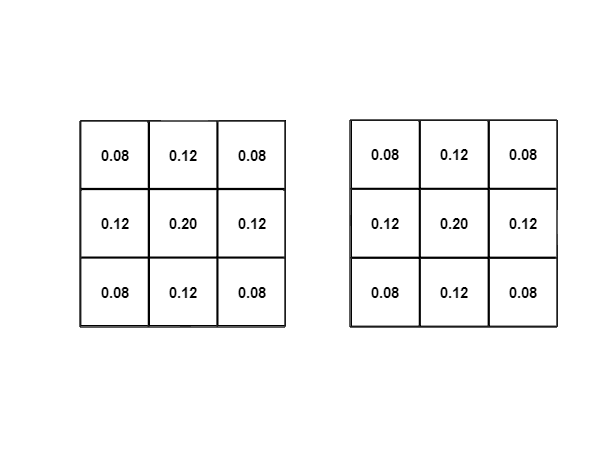

clear; close all; clc;

h = fspecial('gaussian',3,1);

numSize = 3;
[x, y] = meshgrid(1:numSize); 
x = x-(round(numSize/2));
y = y-(round(numSize/2));
sigma = 1;

G_sigma = 1/(2*pi*sigma^2)*exp(-(x.^2 + y.^2)/(2*sigma^2));
G_sigma = G_sigma/sum(G_sigma,'all');

figure(1); 
subplot(121); PlotMat(h,gca,'float'); % from MATLAB built-in function
subplot(122); PlotMat(G_sigma,gca,'float'); % from equation

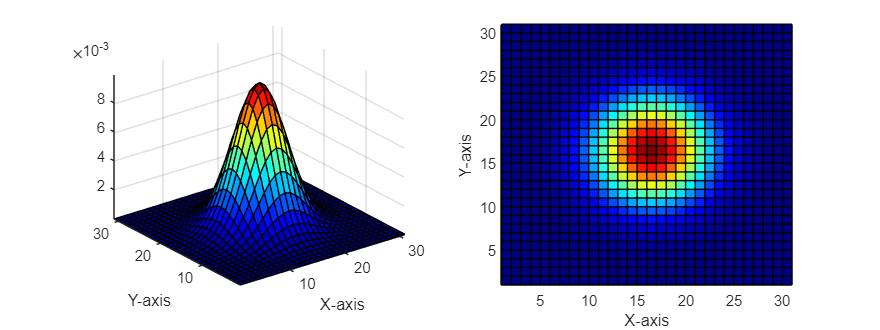


fig2 = figure(2);
subplot(121); h = fspecial('gaussian', 31,4);
surf(h); axis tight; colormap(jet)
set(fig2,'Position', [100 100 800 300]);
xlabel('X-axis'); ylabel('Y-axis');

subplot(122); surf(h); view(0,90);
xlabel('X-axis'); ylabel('Y-axis'); axis tight

### Gaussian Filters

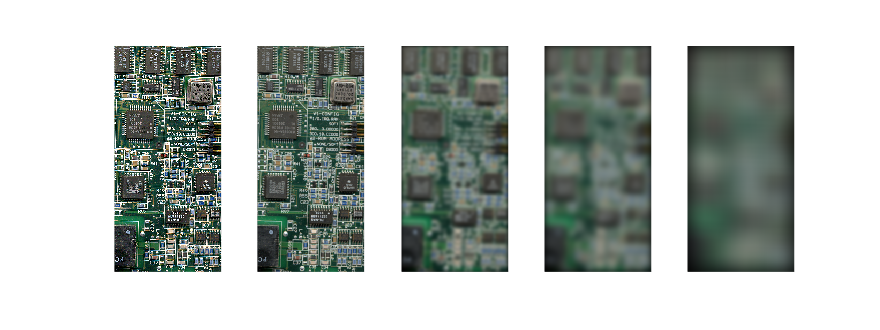

clear; close all; clc;

img = imread('board.tif');
bbox = [7.5100  152.5100  135.9800  142.9800];
patch = imcrop(img, bbox);

f1 =  fspecial('gaussian', 101,1);
f2 =  fspecial('gaussian', 101,5);
f3 =  fspecial('gaussian', 101,10);
f4 =  fspecial('gaussian', 101,30);

fig1 = figure(1);
subplot(151); imshow(img);
subplot(152); imshow(imfilter(img, f1));
subplot(153); imshow(imfilter(img, f2));
subplot(154); imshow(imfilter(img, f3));
subplot(155); imshow(imfilter(img, f4));
set(fig1,'Position', [100 100 800 300]);

### Gaussian Vs Box Filters

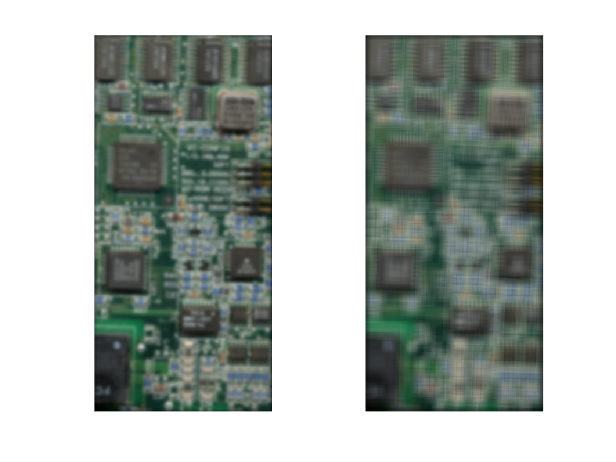

f1 = fspecial('gaussian', 19, 3);
f2 = fspecial('average', 19);

figure(3);
subplot(121); imshow(imfilter(img,f1));
subplot(122); imshow(imfilter(img,f2));

### Image Resizing (Aliasing)

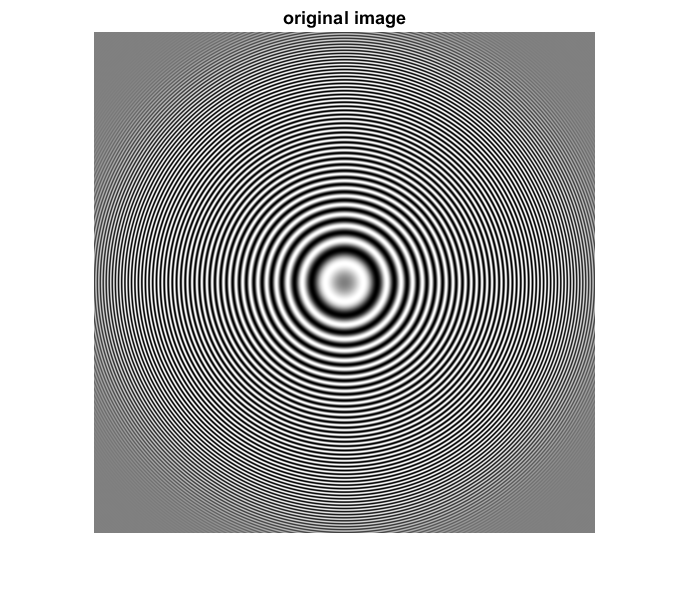

clear; close all; clc;

% https://github.com/mathworks/zone-plate-test-image/blob/master/imzoneplate.m
Z = imzoneplate(501);

figure(1); imshow(Z); title('original image');

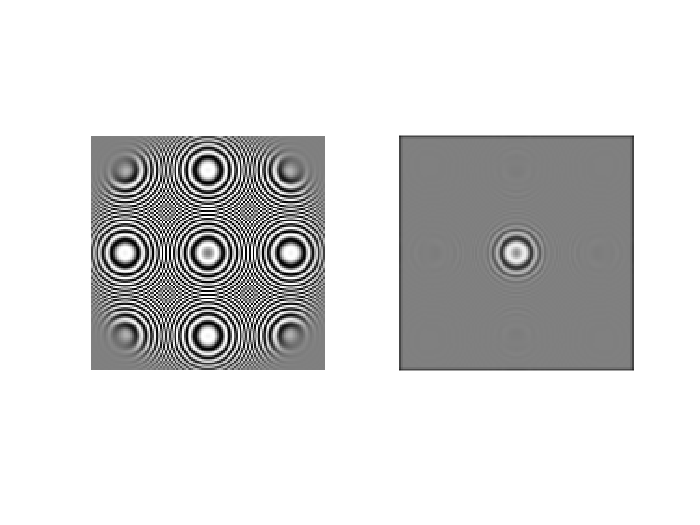


fg =  fspecial('gaussian', 15,4);

figure(2); 

Z1 = Z(1:4:end,1:4:end);
subplot(121); imshow(Z1);

Z2 = imfilter(Z, fg);
Z2 = Z2(1:4:end, 1:4:end);
subplot(122); imshow(Z2);